# Ziegler-Nichols


clc;clear all;close all;
s=tf('s');
Gs=1/(s^2+s+1);
Ts=0.1

Ts = 0.1000

Gz=c2d(Gs,Ts,'zoh');

## 1er Paso, hallar kp=km, ganancia critica

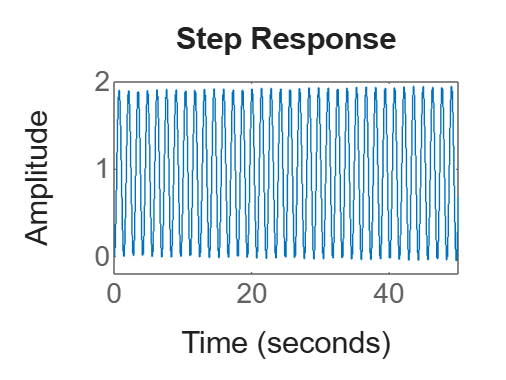

km=20.4;% cambias
K=km;
GCLz=feedback(K*Gz,1);
step(GCLz,50)

## 2do paso, hallar frecuencia de oscilacion del sistema marginalmente estable

tp2=42.1;
tp1=40.7;
Tosc=tp2-tp1;
wm=2*pi*1/Tosc %Hallas esto

wm = 4.4880

## 3er paso, usas formulas

kp=0.6*km;
kd=kp*pi/(4*wm);
ki=kp*wm/pi;
z=tf('z',Ts)


z =
 
  z
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Kz=kp+ki*Ts/2*(z+1)/(z-1)+kd*(z-1)/(Ts*z);
GCLz=feedback(Kz*Gz,1)


GCLz =
 
    0.01669 z^3 - 0.01006 z^2 - 0.01499 z + 0.01001
  ----------------------------------------------------
  0.1 z^4 - 0.2728 z^3 + 0.27 z^2 - 0.1055 z + 0.01001
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


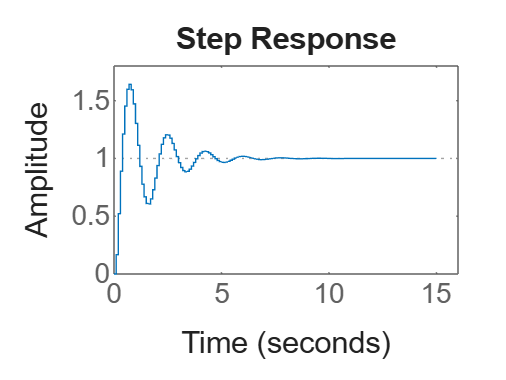

step(GCLz,15)


[Ganan_marginal,~,frec_marginal,~]=margin(Gz)% corroboras, km, wm

Ganan_marginal = 20.3561

frec_marginal = 4.5453